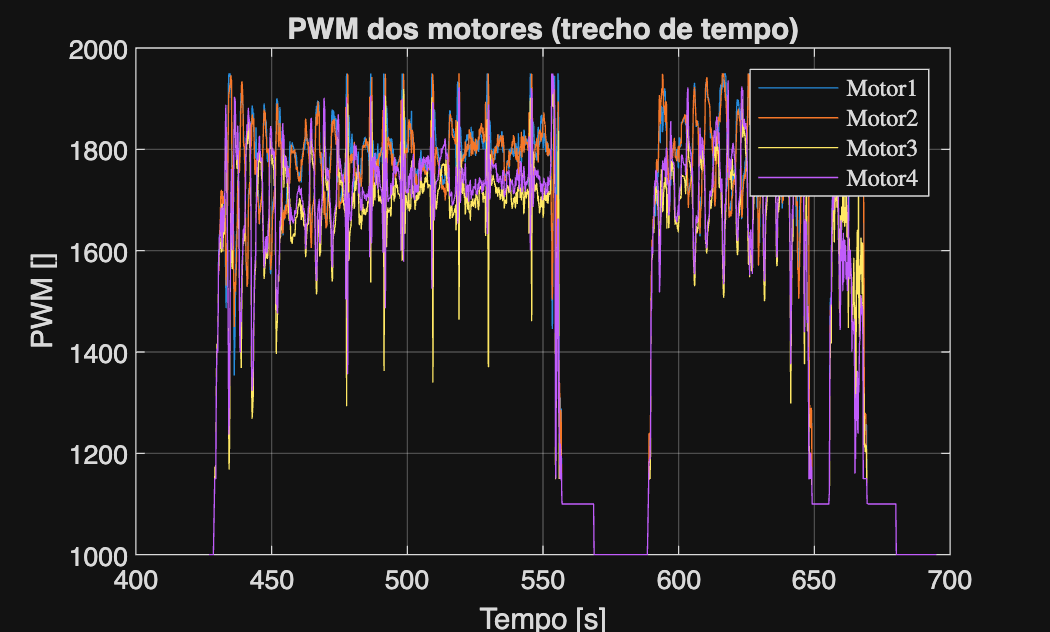

load("1_data/4 25-05-2026 09-31-48.log-132954.mat")

IMU = IMU_0;

gyrX_raw = IMU(:,4);
gyrY_raw = IMU(:,5);
gyrZ_raw = IMU(:,6);

accX_raw = IMU(:,7);
accY_raw = IMU(:,8);
accZ_raw = IMU(:,9);

pwm1_raw = RCOU(:,3);
pwm2_raw = RCOU(:,4);
pwm3_raw = RCOU(:,5);
pwm4_raw = RCOU(:,6);

time_IMU = IMU(:,2) / 1e6;
time_RCOU = RCOU(:,2) / 1e6;


figure;
plot(time_RCOU, pwm1_raw); hold on
plot(time_RCOU, pwm2_raw); hold on
plot(time_RCOU, pwm3_raw); hold on
plot(time_RCOU, pwm4_raw);
xlabel('Tempo [s]');
ylabel('PWM []');
title('PWM dos motores (trecho de tempo)');
legend('Motor1','Motor2','Motor3','Motor4', 'Interpreter', 'latex');
grid on;

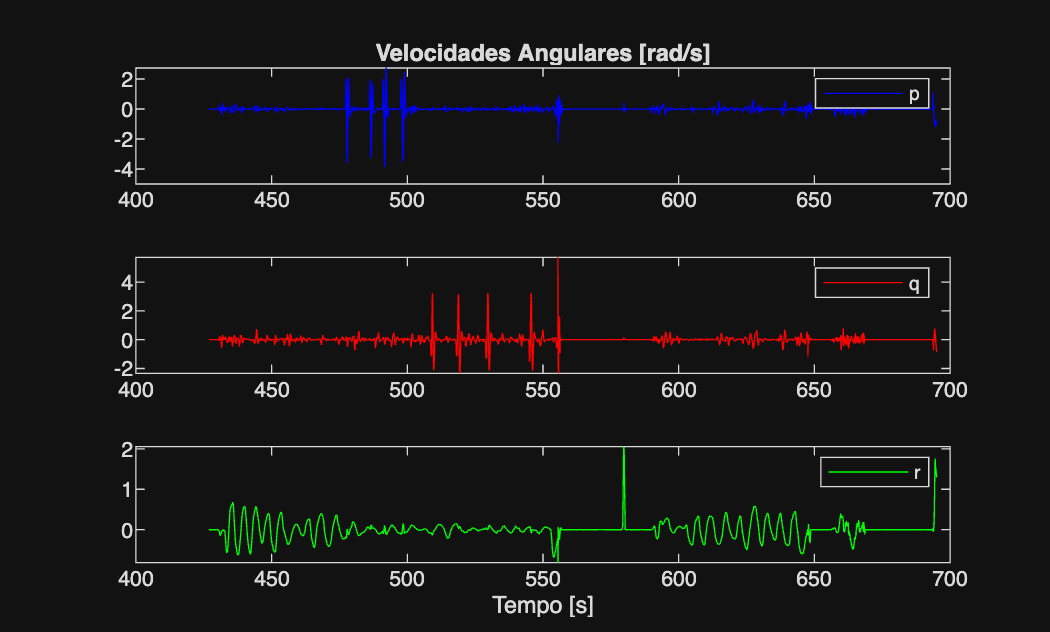


figure
subplot(3,1,1)
plot(time_IMU,gyrX_raw,'Color','b');
title('Velocidades Angulares [rad/s]');
legend('p');
subplot(3,1,2)
plot(time_IMU,gyrY_raw,'Color','r');
legend('q');
subplot(3,1,3)
plot(time_IMU,gyrZ_raw,'Color','g');
legend('r');
xlabel('Tempo [s]');

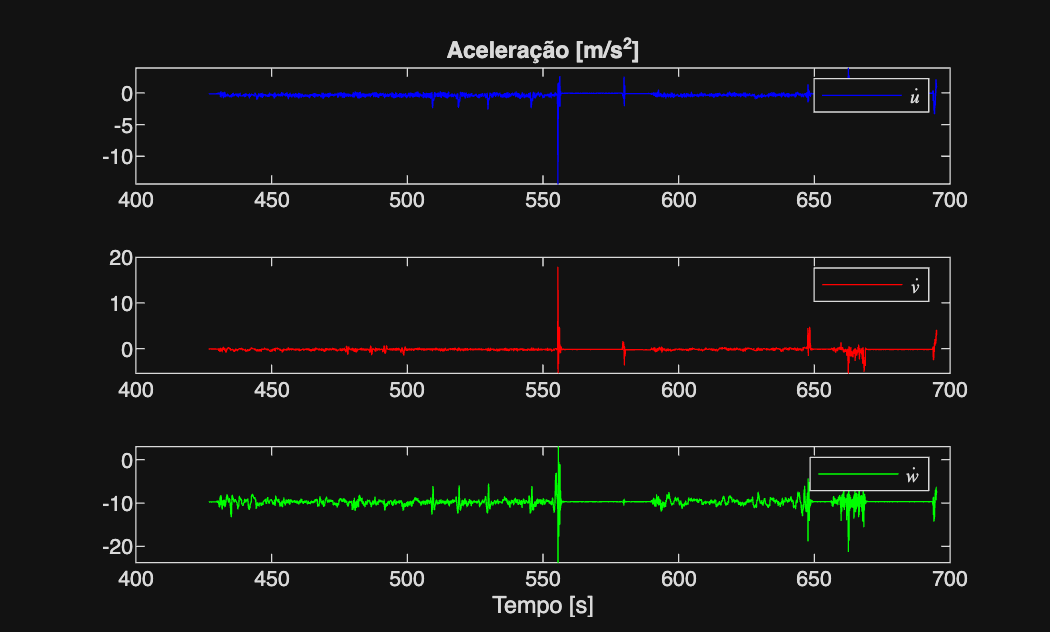



figure
subplot(3,1,1)
plot(time_IMU,accX_raw,'Color','b');
title('Aceleração [m/s^2]');
legend('$\dot{u}$', 'Interpreter', 'latex');
subplot(3,1,2)
plot(time_IMU,accY_raw,'Color','r');
legend('$\dot{v}$', 'Interpreter', 'latex');
subplot(3,1,3)
plot(time_IMU,accZ_raw,'Color','g');
legend('$\dot{w}$', 'Interpreter', 'latex');
xlabel('Tempo [s]');